# Усреднение сигнала с аддитивным белым гауссовским шумом

Создадим синусоиду и добавим к ней АБГШ:

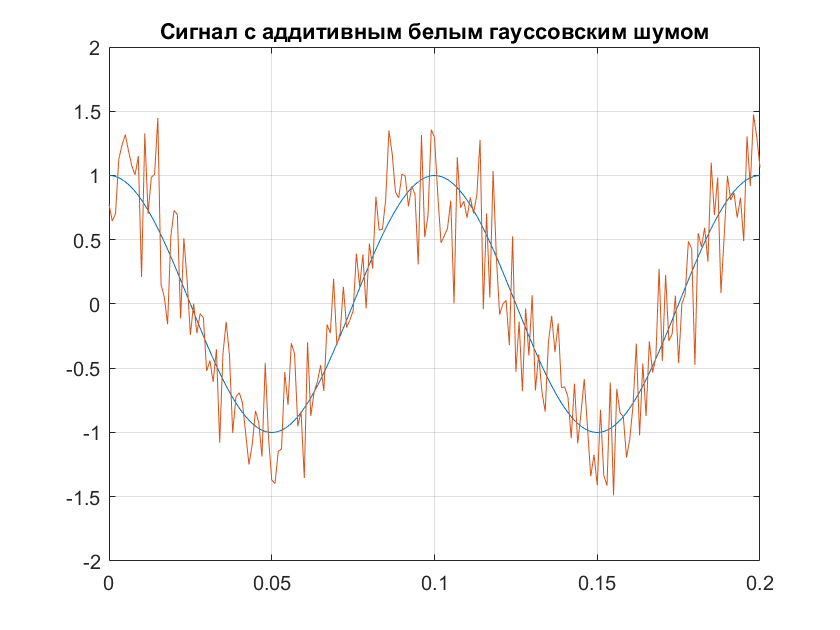

t = 0:1/1000:1;
sine_wave = cos(2*pi*10*t);
plot(t,sine_wave)
xlim([0 0.2]);
ylim([-2 2]);
grid on; hold on;
sine_noise = awgn(sine_wave,10);
plot(t,sine_noise);
hold off;
title('Сигнал с аддитивным белым гауссовским шумом');

Выделим шум из смеси сигнал+шум:

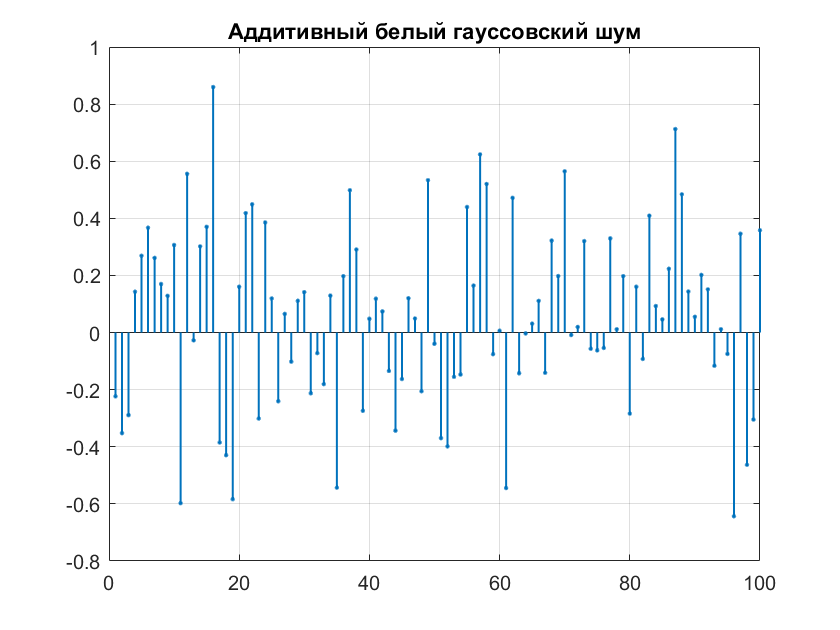

noise = sine_noise - sine_wave;
stem(noise,'LineWidth',1,'Marker','.'); grid on; xlim([0 100]);
title('Аддитивный белый гауссовский шум');

Оценим спектральную плотность мощности шума:

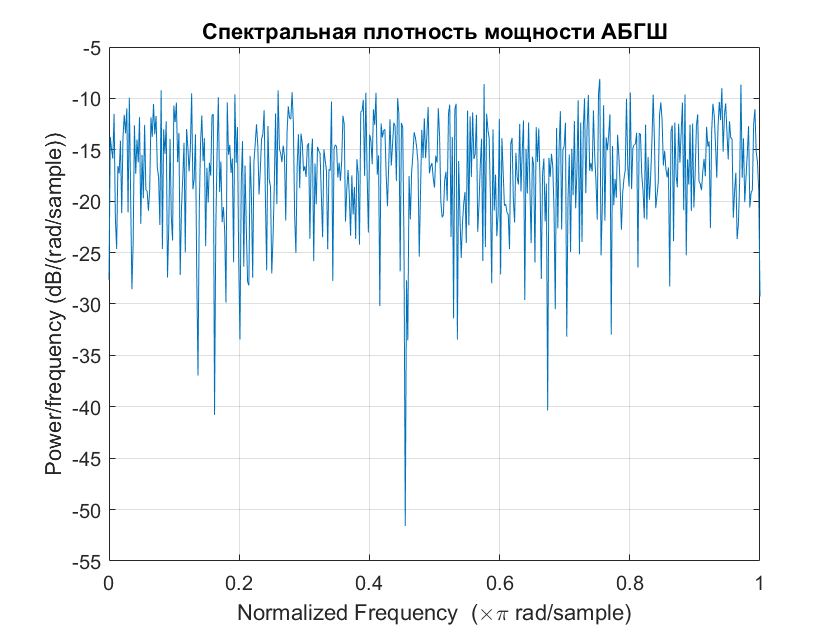

periodogram(noise);
grid on;
title('Спектральная плотность мощности АБГШ');

Построим гистограмму распределения шума:

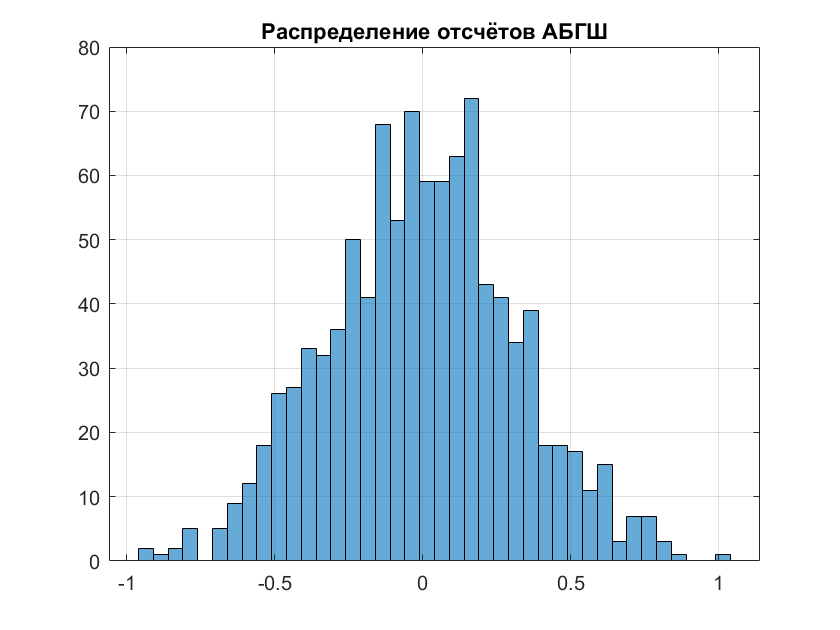

histogram(noise,40);
grid on;
title('Распределение отсчётов АБГШ');

Создадим десять векторов с одинаковой синусоидой, но разными реализациями шума:

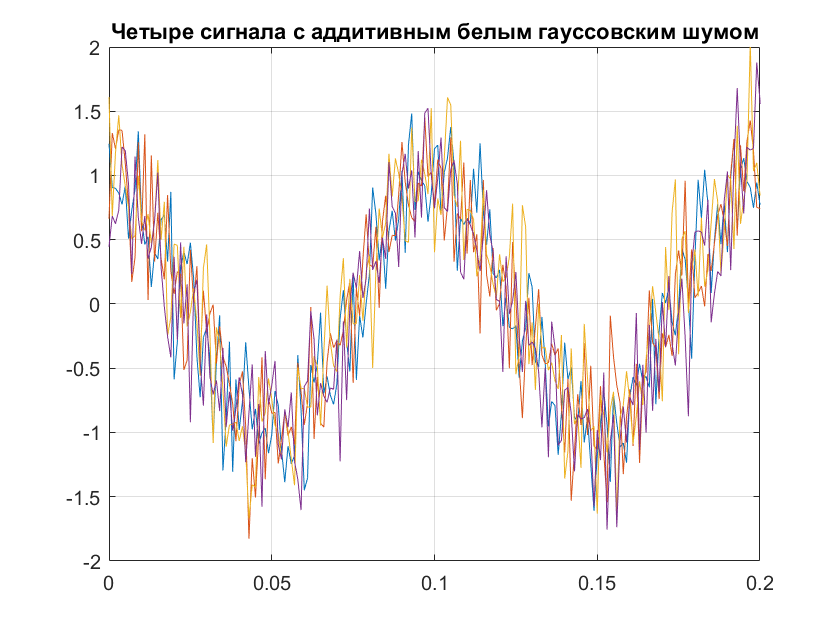

sine1 = awgn(sine_wave,10);
sine2 = awgn(sine_wave,10);
sine3 = awgn(sine_wave,10);
sine4 = awgn(sine_wave,10);
sine5 = awgn(sine_wave,10);
sine6 = awgn(sine_wave,10);
sine7 = awgn(sine_wave,10);
sine8 = awgn(sine_wave,10);
sine9 = awgn(sine_wave,10);
sine10 = awgn(sine_wave,10);

plot(t,[sine1' sine2' sine3' sine4'])
xlim([0 0.2]);
ylim([-2 2]);
grid on;
title('Четыре сигнала с аддитивным белым гауссовским шумом');

Усредним десять векторов и визуализируем результат:

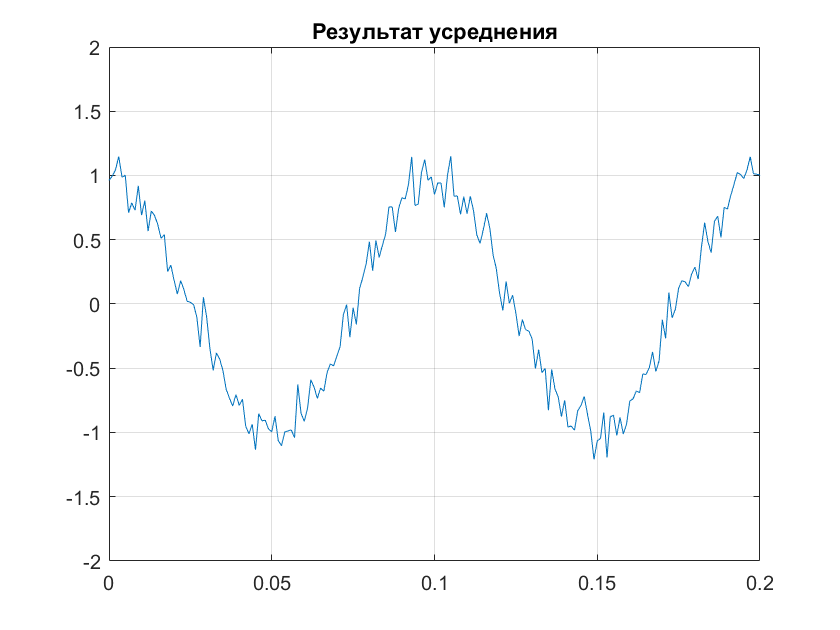

sum_sine = (sine1 + sine2 + sine3 + sine4 + sine5 + ...
    sine6 + sine7 + sine8 + sine9 + sine10)./10;
plot(t,sum_sine);
xlim([0 0.2]);
ylim([-2 2]);
grid on;
title('Результат усреднения');